# Simulazione Veicolo Autobilanciato - gruppo Calegari

## Setup iniziale dell'ambiente

clear
clc
digits(4)
Ts = 0.001;
%load('WS_VAB_wb_0.mat','A','B','C','D','r');
load('WS_VAB_wb_0_5.mat','A','B','C','D','r','J_r');
load('Gains.mat','K_d')

## Sensori

sensitivity_giroscopio = 131*180/pi;%[s/rad]
sensitivity_encoder = 2048;%
sensitivity_arduino = 2^10;

## Costanti del motore

Definizione delle costanti necessarie alla modellizzazione del comportamento del motore.

k_t = 0.1; % Costante di coppia [Nm/A]
R = 0.13; % Resistenza interna del motore[ohm]
L = 0.10e-3; % Induttanza del motore [H]
tau_e = 1.22*10^-3; % Costante di tempo elettrica [m]
tau = 0.1*22/26; % Rapporto di trasmissione
J_m_star = 3.7e-4+double(J_r)*tau^2; %Inerzia del motore ridotta all'albero [kg m^2]
I_max = 20;
C_max = 20*k_t;
fc=1000;
wc=2*pi*fc;
ti_i = tau_e;
kg_i = wc*tau_e*R; 
PI_I = kg_i*tf([ti_i,1],[ti_i,0])


PI_I =
 
  0.001216 s + 0.9965
  -------------------
       0.00122 s
 
Continuous-time transfer function.



PI_I_coeff = (kg_i*[ti_i,1])./(kg_i*[ti_i]);
P = PI_I_coeff(1);
I = PI_I_coeff(2);
motor_selection = 1;

## Modellizzazione del motore

Il primo parametro che andiamo a definire rappresenta l'inerzia del rotore ridotta allìalbero motore.

Per costruzione, è presente una trasmissione a cinghia che presenta un passo 8: essendo il passo uguale per entrambe le pulegge, si ha che l'effettivo diametro delle pulegge stesse, nel calcolo del rapporto di trasmissione, viene a cadere, e quindi risulta essere sufficiente andare ad effettuare il rapporto tra il numero di denti delle pulegge:

 
$$\tau =\frac{n_{\mathrm{in}\;} }{n_{\mathrm{out}} }$$


tau = 0.1*22/26;
J_rotore = double(J_r) * tau^2;
Ts_motore = 0.0001;
showBode = false;
motor = ConfigDCMotor(1, J_rotore, showBode);
currentClosedLoop = CurrentLoop(motor, showBode, Ts_motore);


PI_I_d =
 
  1.037 z - 0.9557
  ----------------
       z - 1
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



## Analisi stabilità e discretizzazione

A_real = double(A);
B_real = double(B);
C_real = double(C);
D_real = double(D);
states = {'phi' 'phi_dot' 'theta' 'theta_dot'};
inputs = {'Cm'};
outputs = {'phi' 'phi_dot' 'theta' 'theta_dot'};
sys = ss(A_real,B_real,C_real,D_real,'statename',states,'inputname',inputs,'outputname',outputs); % Same of G
sys_d = c2d(sys,Ts, 'tustin');
A_d = sys_d.a;
B_d = sys_d.b;
C_d = sys_d.c;
D_d = sys_d.d;

## Simulazione

### Condizioni iniziali

% Initial condition for open loop model
x_0 = [0; 0; 4 * pi / 180; 0];
phi_iniziale = x_0(1);
phi_p_iniziale = x_0(2);
theta_iniziale = x_0(3);
theta_p_iniziale = x_0(4);
r_simulazione = double(r);
control_on = 1;
t_end = 50;
phi_p_setpoint = 10;
m_c_simulazione = double(70); % Vale solo nel non lineare
k_simulazione_discreta = K_d;
discreteTime = 0:Ts:t_end;
phi_p_setpoint = 1;

## Simulazione discreta

### Sistema lineare

clearvars("integrator_controller","integrator_controller_motor","m_a_motore","m_a_phi","m_a_phi_p","m_a_theta","m_a_theta_p","theta_precedente","phi_precedente")
disp('Closed loop');

Closed loop


disp('Linear discrete system');

Linear discrete system


simOut = sim('VAB_Linear_Discrete_function');

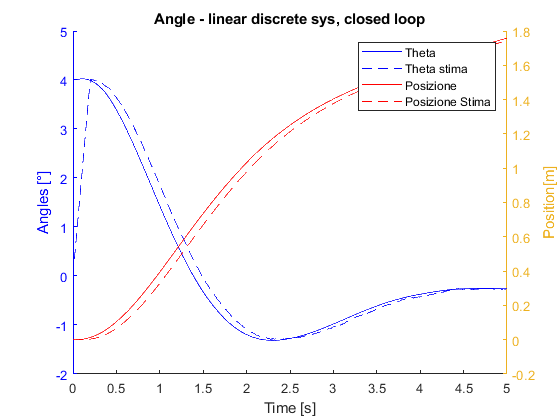

completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torqueRequested = simOut.torqueRequested;
actualTorque = simOut.actualTorque;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

sensor_state = simOut.sensor_state;

figure
hold on
plot(tout, thetaClamped,'b',discreteTime,radtodeg(sensor_state(:,3)),'--','Color','b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione,'r',discreteTime,sensor_state(:,1)*r_simulazione,'--','Color','r')
legend('Theta','Theta stima','Posizione','Posizione Stima');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - linear discrete sys, closed loop')
hold off

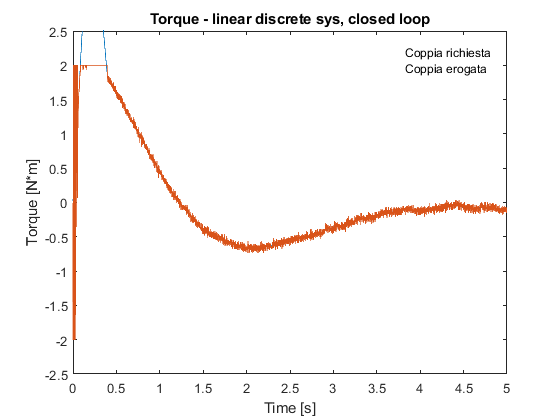


figure
plot(discreteTime, [torqueRequested,actualTorque])
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - linear discrete sys, closed loop')
legend('Coppia richiesta', 'Coppia erogata');
ylim([-2.5 2.5])
hold off

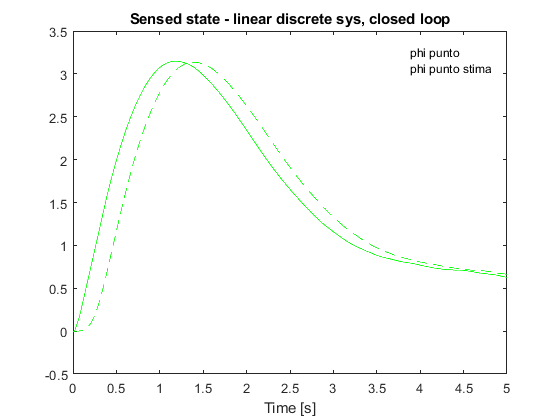

figure
plot(tout,completeState(:,2),'g',discreteTime, sensor_state(:,2),'--','Color','g')
xlabel('Time [s]')
title('Sensed state - linear discrete sys, closed loop')
legend('phi punto', 'phi punto stima');
hold off

## Sistema non lineare

clearvars("integrator_controller","integrator_controller_motor","m_a_motore","m_a_phi","m_a_phi_p","m_a_theta","m_a_theta_p","theta_precedente","phi_precedente")
disp('Non linear discrete system');

Non linear discrete system


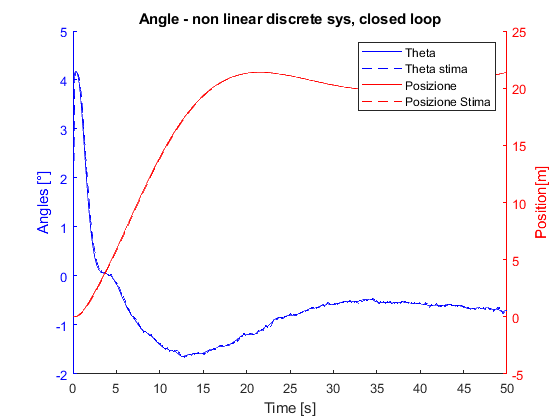

simOut = sim('VAB_non_linear_Discrete_function.slx');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torqueRequested = simOut.torqueRequested;
actualTorque = simOut.actualTorque;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;
sensor_state = simOut.sensor_state;

figure
hold on
plot(tout, thetaClamped,'b',discreteTime,radtodeg(sensor_state(:,3)),'--','Color','b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione,'r',discreteTime,sensor_state(:,1)*r_simulazione,'--','Color','r')
legend('Theta','Theta stima','Posizione','Posizione Stima');
ax = gca;
ax.YAxis(1).Color = 'b';
ax.YAxis(2).Color = 'r';
title('Angle - non linear discrete sys, closed loop')
hold off

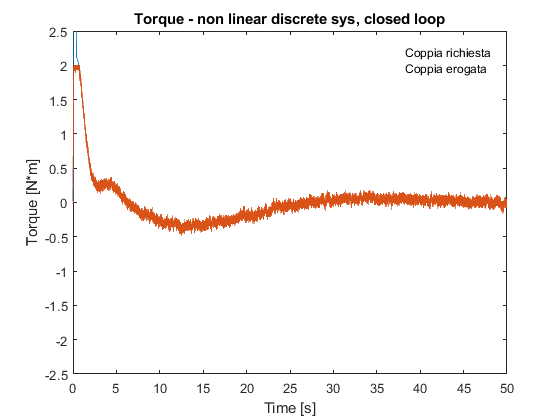

figure
plot(discreteTime, [torqueRequested,actualTorque])
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - non linear discrete sys, closed loop')
legend('Coppia richiesta', 'Coppia erogata');
ylim([-2.5 2.5])
hold off

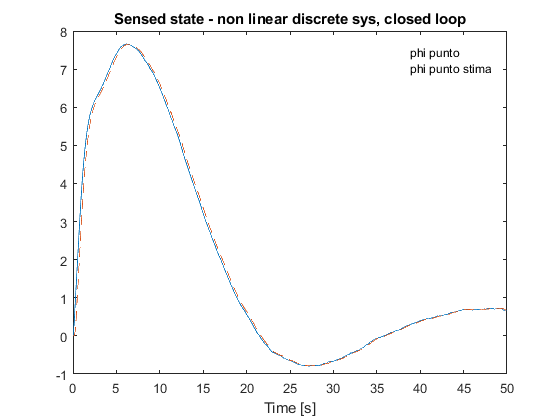

figure
plot(tout,completeState(:,2),discreteTime, sensor_state(:,2),'--')
xlabel('Time [s]')
title('Sensed state - non linear discrete sys, closed loop')
legend('phi punto', 'phi punto stima');
hold off

clearvars ax

### Simulazione con masse diverse

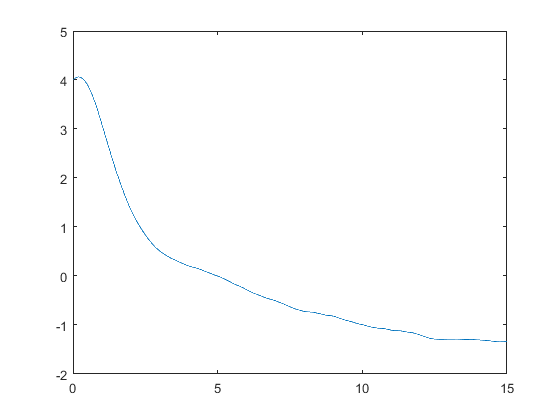

Error due to multiple causes.

Caused by:
    Error using VAB_simulazioni_discrete_function (line 154)
    Program interruption (Ctrl-C) has been detected.
    Error using VAB_simulazioni_discrete_function (

phi_p_setpoint = 0;
masse = [70,60,50,40];
t_end = 15;

for i = 1:length(masse)
    m_c_simulazione = masse(i);
    simOut = sim('VAB_non_linear_Discrete.slx');
    completeState = simOut.completeState;
    out = simOut.Output;
    thetaClamped = simOut.theta_Clamped;
    phiClamped = simOut.phi_Clamped;
    torqueRequested = simOut.torqueRequested;
    actualTorque = simOut.actualTorque;
    tout = simOut.tout;
    posizione = phiClamped*r_simulazione;
    sensor_state = simOut.sensor_state;
    plot(tout,thetaClamped)
    hold on
end

legend(num2str(masse(1)),num2str(masse(2)),num2str(masse(3)),num2str(masse(4)))
title("non linear discrete sys, closed loop, no velocity setpoint'")
hold off
phi_p_setpoint = 1;
for i = 1:length(masse)
    m_c_simulazione = masse(i);
    simOut = sim('VAB_non_linear_Discrete.slx');
    completeState = simOut.completeState;
    out = simOut.Output;
    thetaClamped = simOut.theta_Clamped;
    phiClamped = simOut.phi_Clamped;
    torqueRequested = simOut.torqueRequested;
    actualTorque = simOut.actualTorque;
    tout = simOut.tout;
    posizione = phiClamped*r_simulazione;
    sensor_state = simOut.sensor_state;
    plot(tout,thetaClamped)
    hold on
end
legend(num2str(masse(1)),num2str(masse(2)),num2str(masse(3)),num2str(masse(4)))
title("non linear discrete sys, closed loop, velocity setpoint'")
hold off

NB: State needs to be defined in rad!

%call_plot(completeState * pi / 180);